# This is the Live Editor for Cape Boundy

Saving daily data instead of hourly

%%%%%%%%
% Reading Upper Kuparuk River Basin data
%%%%%%%%
clear all;
close all;


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%FIGURES%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
colors = [179,0,0
227,74,51
252,141,89
253,204,138
254,240,217]./255;



% prepare formating options
HA = {'HorizontalAlignment','left','center','right'};
VA = {'VerticalAlignment','bottom','middle','top'};
UN = {'Units','Normalized','Inches'};
TX = {'Interpreter','Latex'};
TL = {'TickLabelInterpreter','Latex'};
LW = {'LineWidth',1,1.25,1.5,2};
FS = {'FontSize',10,15,18,21,24};
MS = {'MarkerSize',6,8,12};
LS = {'LineStyle','-','--','-.',':'};
% LC = {'Color',color};
LL = {'Location','northwest','northeast','southwest','southeast'};



%Plotting profiles
axh = 5;
axw = 1.5*axh;
ahs = 0.15;
avs = 0.15;
axb = 0.7;
axt = 0.5;
axl = 1.0;
axr = 0.5;
cbh = axh; cbw = 0.2; ht = 0.05;
fh = axb + 1*axh + 1*avs + 1*ht + axt ;
fw = axl  + axw + ahs + cbw + axr;

catchmentA = 2.1e11;%0.21 km^2 --> mm^2
hour1 = 3600; %seconds 
m3    = 1e9; %mm^3 
txtname = 'CB_thawingdepth_dist_hourly.txt';
workdir   = '/Users/cansu/Documents/Polybox_ETH/Permafrost/Cape_Bounty/';
workdirERRA = '/Users/cansu/Documents/GitHub/Permafrost_ERRA/datERRA/CB_thawingdepth_disturbed';
filename = 'CC_Beel_et_al_PT_disturbed_dataset.csv';
filename_p = 'CC_WestMet 2003-23_Summary.csv';
writetables = true;


## Discharge

cd(workdir)
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["DateTime", "Qm3s", "SSCmgL", "POCmgL", "DOCmgL", "TDSmgL"];
opts.VariableTypes = ["datetime", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "DateTime", "InputFormat", "MM/dd/yy HH:mm");

% Import the data
M_ = readtable(filename, opts);

%MANUEL: Some dates MAY not read by Matlab, so lets add those days
%back in
missingdate = isnan(decyear(M_.DateTime));
missingdate_index = find(missingdate);
if length(missingdate_index)>1
    for i = 1:length(missingdate_index)
        j = missingdate_index(i);                         %index of the missing value in M_
        dtt = M_.DateTime(j-1)-M_.DateTime(j-2);  %time step from the previous times
        M_.DateTime(j) = M_.DateTime(j-1)+dtt;    %fill in the missing days
        %TEST: if there is a date in the following point, does it match
        %our dt stepping algorithm?
        if j+1~= missingdate_index(i+1)                   %is the next i index the same as the missing index?
            if M_.DateTime(j) + dtt ~= M_.DateTime(i+1)
                error('STOP: missing data algorithm failed')
            end
        end
        dttold = dtt;
        if dttold ~= dtt
            error('dtt changed')                %This is not an issue, but I did not test this algorithm for when dttold ~= dtt
        end
    end
end


[trash_ index_trash] = unique(M_.DateTime,'rows');               %take the date data
M_trash = M_(index_trash,:);
missingdate = isnan(decyear(M_trash.DateTime));
missingdate_index = find(missingdate);
M_trash(missingdate_index,:) = [];     %if data is still missing, remove row
M = M_trash;
M.Qm3s(ismember(M.Qm3s,7777)) = NaN;
M.Qm3s(ismember(M.Qm3s,6999)) = NaN;
t_ = M.DateTime;
t_cont = t_(1):hours(1):t_(end); 
index_time_o = find(ismember(t_,t_cont)); %%% index of the original data
index_time_s = find(ismember(t_cont,t_)); %%% index of the continuous data

%export discharge
Q_ = M.Qm3s(index_time_o);
Q_cont = nan(size(t_cont));
Q_cont(index_time_s) = Q_; 

%export SSC Suspended Sediment
SSC_ = M.SSCmgL(index_time_o);
SSC_cont = nan(size(t_cont));
SSC_cont(index_time_s) = SSC_; 

%export POC
POC_ = M.POCmgL(index_time_o);
POC_cont = nan(size(t_cont));
POC_cont(index_time_s) = POC_; 

%export DOC
DOC_ = M.DOCmgL(index_time_o);
DOC_cont = nan(size(t_cont));
DOC_cont(index_time_s) = DOC_; 

%convert time to dateyears
t_cont_num = decyear(t_cont);

%plot it
% figQ_plot(t_cont_num,Q_cont,workdir,1)


## Precipitation, Air temperature

cd(workdir)
%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["DateTime", "HourlyAvgAirTempDegC", "TotalHourlyRainfallmm"];
opts.VariableTypes = ["datetime", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "DateTime", "InputFormat", "MM/dd/yy HH:mm");

% Import the data
Mp_ = readtable(filename_p, opts);

%MANUEL: Some dates are actually not read by Matlab, so lets add those days
%back in
missingdate = isnan(decyear(Mp_.DateTime));
missingdate_index = find(missingdate);
for i = 1:length(missingdate_index)
    j = missingdate_index(i);                         %index of the missing value in Mp_
    dtt = Mp_.DateTime(j-1)-Mp_.DateTime(j-2);  %time step from the previous times
    Mp_.DateTime(j) = Mp_.DateTime(j-1)+dtt;    %fill in the missing days
    %TEST: if there is a date in the following point, does it match
    %our dt stepping algorithm?
    if j+1~= missingdate_index(i+1)                   %is the next i index the same as the missing index?
        if Mp_.DateTime(j) + dtt ~= Mp_.DateTime(i+1)
                error('STOP: missing data algorithm failed')
        end
    end
    dttold = dtt;
    if dttold ~= dtt
        error('dtt changed')
    end
end

%check that the date does not appear multiple times
[trash_ index_trash ic] = unique(Mp_.DateTime,'rows');               %take the date data
Mp_trash = Mp_(index_trash,:);
% [trash_ I] = rmmissing(Mp_trash); %find missing data
% Mp_trash(I,:) = NaN;
Mp = Mp_trash;

%remove bad data
Mp.TotalHourlyRainfallmm(ismember(Mp.TotalHourlyRainfallmm,7777)) = NaN;
Mp.TotalHourlyRainfallmm(ismember(Mp.TotalHourlyRainfallmm,6999)) = NaN;
Mp.HourlyAvgAirTempDegC(ismember(Mp.HourlyAvgAirTempDegC,7777)) = NaN;
Mp.HourlyAvgAirTempDegC(ismember(Mp.HourlyAvgAirTempDegC,6999)) = NaN;


tp_     = Mp.DateTime;
tp_cont = tp_(1):hours(1):tp_(end)

tp_cont = 1×176549 datetime array
Columns 1 through 1424

   08-Jun-2003 19:00:00   08-Jun-2003 20:00:00   08-Jun-2003 21:00:00   08-Jun-2003 22:00:00   08-Jun-2003 23:00:00   09-Jun-2003 00:00:00   09-Jun-2003 01:00:00   09-Jun-2003 02:00:00   09-Jun-2003 03:00:00   09-Jun-2003 04:00:00   09-Jun-2003 05:00:00   09-Jun-2003 06:00:00   09-Jun-2003 07:00:00   09-Jun-2003 08:00:00   09-Jun-2003 09:00:00   09-Jun-2003 10:00:00   09-Jun-2003 11:00:00   09-Jun-2003 12:00:00   09-Jun-2003 13:00:00   09-Jun-2003 14:00:00   09-Jun-2003 15:00:00   09-Jun-2003 16:00:00   09-Jun-2003 17:00:00   09-Jun-2003 18:00:00   09-Jun-2003 19:00:00   09-Jun-2003 20:00:00   09-Jun-2003 21:00:00   09-Jun-2003 22:00:00   09-Jun-2003 23:00:00   10-Jun-2003 00:00:00   10-Jun-2003 01:00:00   10-Jun-2003 02:00:00   10-Jun-2003 03:00:00   10-Jun-2003 04:00:00   10-Jun-2003 05:00:00   10-Jun-2003 06:00:00   10-Jun-2003 07:00:00   10-Jun-2003 08:00:00   10-Jun-2003 09:00:00   10-Jun-2003 10:00:00   10-Jun-2003 11:00:0

index_timep_o = find(ismember(tp_,tp_cont)); %%% index of the original data
index_timep_s = find(ismember(tp_cont,tp_)); %%% index of the continuous data

%export discharge
P_ = Mp.TotalHourlyRainfallmm(index_timep_o);
P_cont = nan(size(tp_cont));
P_cont(index_timep_s) = P_; 

%export air temperature
AT_ = Mp.HourlyAvgAirTempDegC(index_timep_o);
AT_cont = nan(size(tp_cont));
AT_cont(index_timep_s) = AT_;


%convert time to dateyears
tp_cont_num = decyear(tp_cont);

% 
% figP_plot(tp_,Mp.TotalHourlyRainfallmm,workdir,1)
% figP_plot(tp_cont_num,P_cont,workdir,1)

Test: to see if the P_ and P_cont match up

% figure
% plot(decyear(tp_),P_,'-r')
% hold on
% plot(tp_cont_num,P_cont,'-b')
% 
% figure
% plot(decyear(tp_),AT_,'-r')
% hold on
% plot(tp_cont_num,AT_cont,'-b')

## Make the same data size

index_Q_match_P_1 =  find(ismember(tp_cont,t_cont(1)));
index_Q_match_P_end =  find(ismember(tp_cont,t_cont(end)));

shortP_cont_match_Q = [P_cont(index_Q_match_P_1:index_Q_match_P_end)]';
shortAT_cont_match_Q = [AT_cont(index_Q_match_P_1:index_Q_match_P_end)]';


## We do not have Thaw Depth Data but we can estimate Thaw Depth from Air Temperature

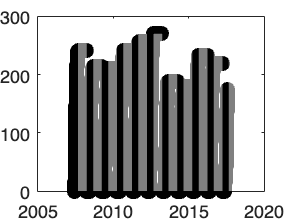

months = month(t_cont);
cd(workdirERRA);
[Z, dZ] = ModelingThawDepth_sqrtDDT(decyear(t_cont),months,shortAT_cont_match_Q);

## Save files to txt

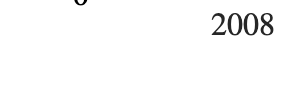

ans =   Figure (11) with properties:

      Number: 11
        Name: ''
       Color: [1 1 1]
    Position: [0.7000 12 21.6000 6.2500]
       Units: 'inches'

  Show all properties


%First make a table
time_cont = decyear(t_cont)';
years = year(t_cont)';
months = month(t_cont)';
airtemp = shortAT_cont_match_Q;
P = shortP_cont_match_Q;
Q = Q_cont'*hour1*m3/catchmentA; %<-- convert to m^3/s mm/hr
ThawDepth = Z(1:end-1)';
dZ = dZ';
dw30 = 0.3.*10.*dZ; %<-- convert dZ to amount of water (assume 30% water)and cm to mm
figtQP_plot_UK_wiMatlab(time_cont,Q,P,workdir,1)

Mtxt = table(time_cont,years,months,...
    airtemp,P,Q,ThawDepth,dZ,dw30);
if writetables ==1
    cd(workdirERRA)
    writetable(Mtxt,txtname,'WriteRowNames',true,'Delimiter',',');
 end

